**Question 1:**

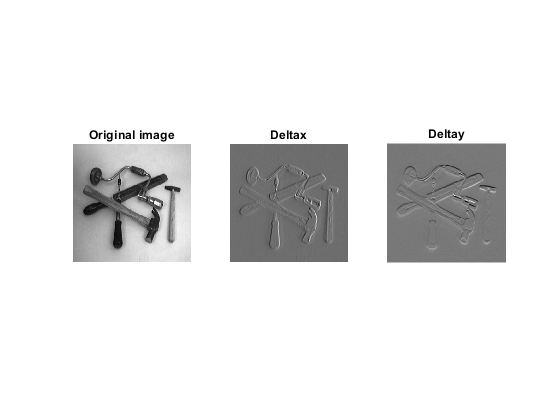

deltax = [1 0 -1; 2 0 -2; 1 0 -1];
deltay = [1 2 1; 0 0 0; -1 -2 -1];
tools = few256;
dxtools = conv2(tools, deltax, 'valid');
dytools = conv2(tools, deltay, 'valid');
figure()
subplot(1,3,1);
showgrey(tools);
title("Original image")
subplot(1,3,2);
showgrey(dxtools);
title("Deltax")
subplot(1,3,3);
showgrey(dytools);
title("Deltay")

We expect to see contrast when the derivative is high in x for the dxtools and similarly for y. This can easily be seen in the screwdriver handle. For y, it has a higher "activation" than in y.

The sizes are different because of the 3x3 filter. conv2 with valid returns only pixels where the whole filter fits, which for a 3x3 filter causes 2 rows and columns to be removed. If we use 'same' instead of 'valid' this doesn't happen. 

**Question 2 & 3.**

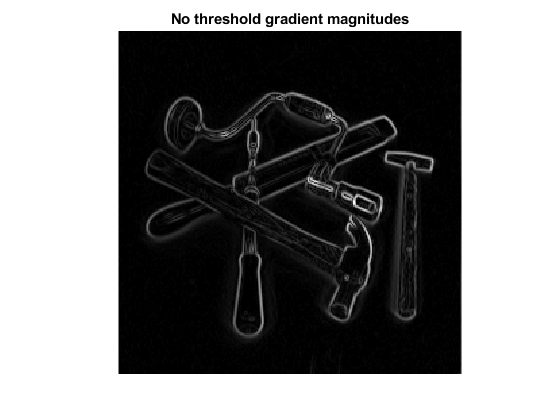

figure()
thresholds = linspace(20,60,16);
gradmagntools = sqrt(dxtools .^2 + dytools .^2);
showgrey(gradmagntools);
title("No threshold gradient magnitudes");

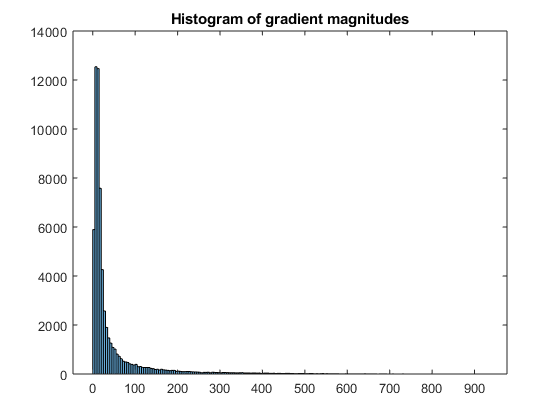

histogram(gradmagntools);
title("Histogram of gradient magnitudes");

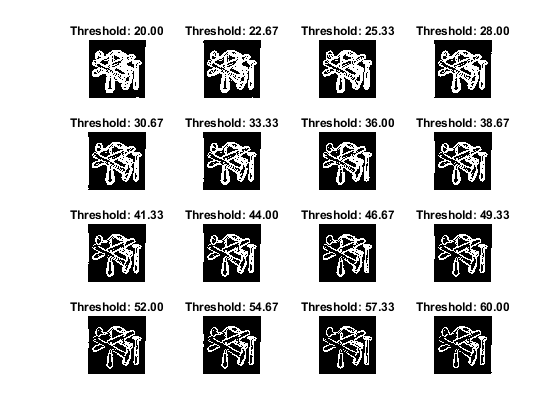


thresholdcomp(tools, thresholds);

It is not easy to find a threshold that results in a smooth image. This could be because of smoothing, which results in wider edges. Smoothing helps with finding edges because it removes a lot of noise reduces the magnitude of the gradient.

**Question 4:**

figure()
house = godthem128;
size(house)

ans =    128   128


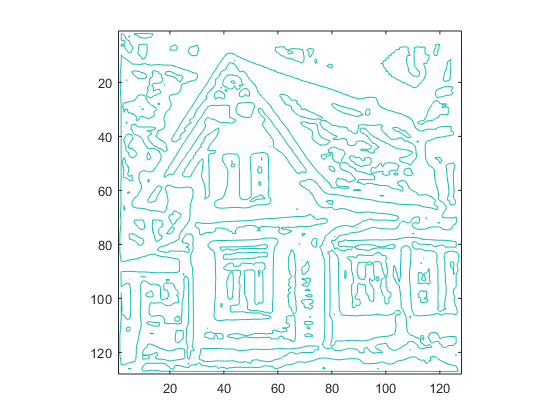

contour(Lvvtilde(discgaussfft(house, 2)), [0 0])
axis('image')
axis('ij')